# Simulate Channel Compression Effect on Precoding Using MATLAB and Keras with CSINet

This example shows how to co-execute MATLAB® and Keras™ to simulate the effect of channel estimate compression on precoding in a MIMO OFDM channel.

## Introduction

In this example, you will learn how to co-execute MATLAB and Python® to test a pretrained Keras CSINet model in an OFDM MIMO link simulation. The example uses the CSINet models published in [1] and [2]. Note that the pre-trained model were trained using a COST2100 channel model data set. In this example, you will test the CSINet model with a CDL channel data set, generated using [5G Toolbox](https://www.mathworks.com/products/5g.html)™ in MATLAB, and use transfer learning to fine tune the networks weights to the new channel model by co-executing MATLAB and Keras. Finally, you will simulate the effect of precoding with CSINet feedback in a point-to-point OFDM MIMO channel. 

The following figure summarizes the operations executed in MATLAB (marked in blue) versus those executed in Keras (marked in grey). Note that MATLAB is the master environment driving this example throughout. 

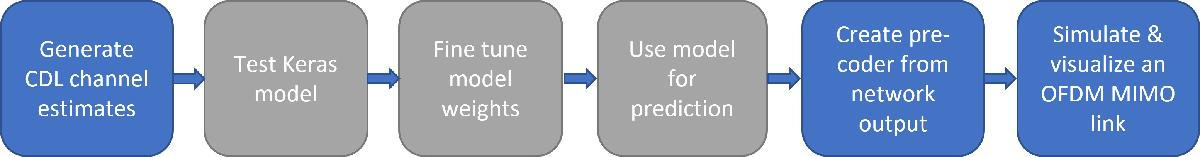

### CSINet overview

CSINet is an autoencoder deep neural network, proposed in [1], to compress channel feedback in massive MIMO systems. The CSINet model in [1] is trained using an OFDM channel response generated through the COST 2100 channel model and published in [2]. Two channel scenarios are considered: an indoor Pico-cellular scenario at 5.3 GHz and an outdoor rural scenario at the 300 MHz band. An OFDM channel is simulated between a BS with 32 transmit antennas and a UE with one receive antenna. The number of OFDM subcarriers is set to 1024. The channel response matrices are transformed from the frequency-spatial domain to the angular-delay domain by applying a 2-D Fourier transform. In the angular-delay domain, only the first 32 rows of the delay dimension is retained for training and testing. After training, the autoencoder network is split into an encoder and a decoder. The receiver uses the encoder to compress the estimated channel matrix into a 1-D array of dimension L-by-1 and feeds it back to the transmitter. Afterwards, the transmitter uses the decoder to recover the compressed channel estimate.

## Setup Python environment

To configure your system to use Python, see [Configure Your System to Use Python](https://www.mathworks.com/help/matlab/matlab_external/install-supported-python-implementation.html). By default, MATLAB selects the version of Python based on your system path. To see which version MATLAB is using call [pyenv](https://www.mathworks.com/help/matlab/ref/pyenv.html) function. If you have any library conflicts between MATLAB and Python, try using [Out-of-Process Execution of Python Functionality](https://www.mathworks.com/help/matlab/matlab_external/out-of-process-execution-of-python-functionality.html). For supported Python version information, see [Versions of Python Compatible with MATLAB Products by Release](https://www.mathworks.com/support/requirements/python-compatibility.html).

pyenv("ExecutionMode","InProcess")

ans =   PythonEnvironment with properties:

          Version: "3.10"
       Executable: "C:\Users\username\Python\Python310\pythonw.exe"
          Library: "C:\Users\username\Python\Python310\python310.dll"
             Home: "C:\Users\username\Python\Python310"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "34680"
      ProcessName: "MATLAB"


You need the following Python libraries to be installed prior to running this example:

- Tensorflow™ (tested with Tensorflow 2.10.0)

- Keras (tested with Keras 2.10.0)

- Numpy™ (tested with Numpy 1.23.4)

## CDL channel data set

A pre-processed data set of CDL channel perfect estimates was generated by following the steps in [CSI Feedback with Autoencoders](https://www.mathworks.com/help/comm/ug/csi-compression-autoencoder.html). It uses the following parameters for the CDL channel model:

- Tx Antennas: 32

- Rx Antennas: 2

- Delay Profile: CDL-B

- RMS delay spread: 100 ns

- Max delay after truncation: 32

- Max Doppler: 2 Hz

- Resource blocks: 48 

- Subcarrier spacing: 30 KHz

By default, this example downloads the pre-processed dataset and the pretrained CSINet models from [https://ssd.mathworks.com/supportfiles/spc/coexecutionPrecoding/processedData.zip](https://ssd.mathworks.com/supportfiles/spc/coexecutionPrecoding/processedData.zip) and [https://ssd.mathworks.com/supportfiles/spc/coexecutionPrecoding/keras.zip](https://ssd.mathworks.com/supportfiles/spc/coexecutionPrecoding/keras.zip), respectively. If you do not have an Internet connection, you can download the files manually on a computer that is connected to the Internet, unzip and save them to the example directory.

downnloadDataFile();

processedData folder exists. Skip download.

keras folder exists. Skip download.



Load the test dataset to evaluate the accuracy of the network with the CDL channel model. The preprocessing steps includes truncating the complex-valued OFDM channel estimates in the delay-angular domain as well as normalizing the data samples to a mean of 0.5 & standard variation of 0.0212. For more details on the preprocessing steps, see [CSI Feedback with Autoencoders](https://www.mathworks.com/help/comm/ug/csi-compression-autoencoder.html). You can use the helper file [GenerateCSINetDataSet](matlab:open('./GenerateCSINetDataSet.mlx')) to generate and preprocess a dataset with different channel parameters. The test data is saved as MAT files with the prefix `CDLChannelEst_test.`

testSds = signalDatastore(fullfile(pwd,"processedData","CDLChannelEst_test*"));
HTestRealCell = readall(testSds);
HTestReal = cat(1,HTestRealCell{:});

## Load and test the network using Python

Next, you will load the pretrained CSINet from the pre-saved JSON model file & HDF5 weights file. Set the environment and the compression rate to load the corresponding pretrained network and weights. The environment `env` can be set to `indoor` or `outdoor.` The compression rate `compressRate` can be set to $\frac{1}{4}$, $\frac{1}{16}$, $\frac{1}{32}$, or $\frac{1}{64}$.

env = "outdoor"; % "indoor" | "outdoor"
compressRate = 1/4; % 1/4 | 1/16 | 1/32 | 1/64
codewordDim = num2str(numel(HTestReal(1,:,:,:))*compressRate);

Set the path for the model and weights files.

fileName = sprintf('%s',"model_CsiNet_",env,"_dim",num2str(codewordDim));
modelFileName = fullfile(pwd,"keras",fileName+".json");
weightsFileName = fullfile(pwd,"keras",fileName+".h5");

In this section, you will use MATLAB's Python interface to execute Python methods to open and load the model file into MATLAB workspace. You can use the `py.` prefix in MATLAB to execute Python methods as shown in `py.open.` For Python objects, you can call the object methods directly without the `py.` prefix, e.g., `openedModel` is a `TextIOWrapper` object with the methods `read` & `close.`

openedModel = py.open(modelFileName,"r");
modelString = openedModel.read();
openedModel.close();

Use the Keras method `model_from_json` to load the model into MATLAB's workspace. Afterwards, use the Keras method `load_weights` to load the weights onto the model`.` Finally, use the Keras method `summary` and Python's method `print` to view the loaded model.

CSINet = py.tensorflow.keras.models.model_from_json(modelString); 
CSINet.load_weights(weightsFileName)
py.print(CSINet.summary())

Model: "model"
__________________________________________________________________________________________________
 Layer (type)                   Output Shape         Param #     Connected to                     
 input_1 (InputLayer)           [(None, 32, 32, 2)]  0           []                               
                                                                                                  
 conv2d (Conv2D)                (None, 32, 32, 2)    38          ['input_1[0][0]']                
                                                                                                  
 batch_normalization (BatchNorm  (None, 32, 32, 2)   8           ['conv2d[0][0]']                 
 alization)                                                                                       
                                                                                              

### Test the pretrained CSINet with the CDL dataset

You will test the loaded Keras model CSI`Net` with the test dataset `HTestReal` using the Keras method `predict.` `Predict` method expects its input to be an `ndarray`, use `numpy.array` method to cast `HTestReal` to an `ndarray.` Set the `copy` flag to false in `numpy.array` to avoid the overhead of creating a new copy of the data.

xTest = py.numpy.array(HTestReal,copy=false);

tic
xHat = CSINet.predict(xTest,pyargs("verbose",0));
predictionTime = toc;
fprintf("Prediction time is %f s",predictionTime);

Prediction time is 0.832701 s

Compute the normalized mean square error (NMSE) between the input and output of CSI`Net` using the local function `computeNMSE`.

nmsePreTraining = computeNMSE(xTest,xHat) % dB

nmsePreTraining = single
-12.6400

Next, you will use transfer learning to fine tune the weights of CSINet to the new channel model to further decrease the NMSE.

## Fine tune CSINet weights using transfer learning

The downloaded dataset, in the** processedData **directory, includes training and validation data generated for a CDL channel with the same parameters listed in CDL channel data set section. The training & validation datasets are saved as MAT files with the prefixes `CDLChannelEst_train` & `CDLChannelEst_val,` respectively`.`

trainSds = signalDatastore(fullfile(pwd,"processedData","CDLChannelEst_train*"));
HTrainRealCell = readall(trainSds);
HTrainReal = cat(1,HTrainRealCell{:});

valSds = signalDatastore(fullfile(pwd,"processedData","CDLChannelEst_val*"));
HValRealCell = readall(valSds);
HValReal = cat(1,HValRealCell{:});

Set the number of transfer learning epochs to 100 and the batch size to 150. Use Python's `numpy.array` method to cast `HTrainReal` & `HTrainReal` to `ndarray.` Cast `epochs` and `batchSize` to integer data types to match those expected by the Keras method `fit. `

py.random.seed(0)
py.tensorflow.random.set_seed(0)
epochs = uint8(100);
batchSize = uint8(150);
val_freq = uint16(500);
xTrain = py.numpy.array(HTrainReal,copy=false);
xVal = py.numpy.array(HValReal,copy=false);

lr_schedule = py.tensorflow.keras.optimizers.schedules.ExponentialDecay(initial_learning_rate=8e-3, ...
            decay_steps=4000,decay_rate=0.9); 

Use Keras methods `compile` and `fit` on CSI`Net` to compile and train the model. The function [pyargs](https://www.mathworks.com/help/matlab/ref/pyargs.html) in MATLAB allows you to create keyword arguments for Python functions. Training the model using MATLAB's Python interface with Nvidia GeForce RTX 3080 GPU takes about 2 minutes and 10 seconds. Training this model on a CPU might take up to 20 minutes. 

CSINet.compile(pyargs("optimizer",py.keras.optimizers.Adam(learning_rate=lr_schedule),"loss","mse"));
tic
CSINet.fit(xTrain, xTrain,pyargs("epochs",epochs, ...
                "batch_size",batchSize, ...
                "shuffle",true, ...
                "validation_data",{xVal,xVal}, ...
                "validation_freq",val_freq, ...
                "verbose",0));
trainTime = toc;
fprintf("Training time is %f s",trainTime);

Training time is 124.380649 s

Finally, use the Keras method `predict` on CSI`Net` to see the effect of transfer learning on the model's accuracy. Notice that the NMSE drops from -12 dB to slightly below -42 dB.

tic
xHat = CSINet.predict(xTest,pyargs("verbose",0));
predictionTime = toc;
fprintf("Prediction time is %f s",predictionTime);

Prediction time is 0.568174 s

nmsePostTraining = computeNMSE(xTest,xHat) % dB

nmsePostTraining = single
-42.9017

### Save the retrained Keras model

Use Keras method `to_json` on CSI`Net` after transfer learning to serialize the model to JSON format. Similarly, use Keras method `save_weigths` to save the new weights.

newModelDir = fullfile(pwd,"retrainedKeras");

fileName = "model_CsiNet_"+env+"_dim"+num2str(codewordDim);
if ~exist(newModelDir,"dir")
    mkdir(newModelDir);
end
outputWeightsFileName = fullfile(newModelDir,fileName+".h5");
outputModelFileName = fullfile(newModelDir,fileName+".json");

modelJson = CSINet.to_json();
openedOutputFile = py.open(outputModelFileName,"w");
openedOutputFile.write(modelJson);
CSINet.save_weights(outputWeightsFileName);

## Simulate precoded-OFDM link with CDL channel

Use **info** MAT file in the **processedData** directory to load the channel object and channel parameters used to generate the training and testing datasets. Use the same channel object to simulate an OFDM MIMO link in the frequency domain. Examine the effect of channel estimate compression by constructing a zero-forcing precoder from the channel matrix fed back through CSINet. Finally, visualize the compression effect on the received symbols using the [comm.ConstellationDiagram](https://www.mathworks.com/help/comm/ref/comm.constellationdiagram-system-object.html?searchHighlight=comm.constellation&s_tid=srchtitle_comm.constellation_1) object.

load(fullfile(pwd,"processedData","info.mat"));

Nsc = opt.NumSubcarriers;
Nsym = opt.NumSymbols;
Nrx = opt.NumRxAntennas;
Ntx = opt.NumTxAntennas;

Simulate an OFDM MIMO channel in the frequency domain with a zero-forcing precoder. Use the retrained CSINet to compress and decompress the estimated OFDM channel in the frequency domain. Use 16-QAM modulation to view the effect of using the channel estimate after compression and decompression on the received constellation after precoding.

rng(111)
bitsPerSymbol = 4;
numInfoStreams = Nrx;
refConstellation = qammod((0:2^bitsPerSymbol-1)',2^bitsPerSymbol,"UnitAveragePower",true);

scope = comm.ConstellationDiagram( ...
    "SamplesPerSymbol",1, ...
    "ShowReferenceConstellation",true, ...
    "ReferenceConstellation",refConstellation, ...
    "ColorFading",false, ...
    "Title","Received Symbols", ...
    "Name", "Zero-forcing Precoding with CSINet");

bits = randi([0,1],bitsPerSymbol,Nsym,Nsc,numInfoStreams,"int8");

% QAM Modulation
mappedSym = qammod(bits(:),2^bitsPerSymbol,"InputType","Bit", ...
    "UnitAveragePower",true);

% Map modulated symbols on an OFDM Grid
OFDMGridSym = reshape(mappedSym,Nsc,Nsym,numInfoStreams)*sqrt(numInfoStreams);

% Permute OFDMGridSym to numInfoStreams-by-1-by-Nsc-by-Nsym
OFDMGridSym = permute(OFDMGridSym, [3,4,1,2]);

% Step CDL channel object
[pathGains,sampleTimes] = channel();

% Perfect timing synchronization
pathFilters = getPathFilters(channel);
offset = nrPerfectTimingEstimate(pathGains,pathFilters);

% Perfect OFDM channel estimate Nsc-by-Nsym-by-Nrx-by-Ntx
estChannelGrid = nrPerfectChannelEstimate(carrier,pathGains,pathFilters,offset,sampleTimes);

% Preprocess channel estimate
[HtruncReal,meanVal,stdVal] = preprocessChannelEstimate(estChannelGrid,opt);

Compress and decompress the channel estimate `HtruncReal` by directly calling the Keras method `predict` on the retrained `Keras` model `CSINet.`

% Use Keras autoencoder model
xHat = CSINet.predict(py.numpy.array(HtruncReal,copy=false),pyargs("verbose",0));
nmse = computeNMSE(HtruncReal,xHat)

nmse = single
-42.8972

Cast the output of CSINet back into MATLAB's single data type and postprocess the channel matrix using the helper file [postprocessChannelEstimate](matlab:open('./postprocessChannelEstimate.m')). Use the postprocessed channel matrix, `chanFeedback,` to construct a zero-forcing precoder matrix and simulate the precoded-OFDM link. 

chanFeedback = postprocessChannelEstimate(xHat,opt);

% Construct zero-forcing precoding matrix
H_HTrans = pagemtimes(chanFeedback,pagectranspose(chanFeedback));
H_HTrans_inv = pageinv(H_HTrans);
V = pagemtimes(pagectranspose(chanFeedback),H_HTrans_inv);
D = repmat(sqrt(sum(abs(V).^2,1)),Ntx,1,1);
preCoder = repmat(V.*D, [1,1,1,Nsym])*sqrt(Ntx); % Ntx-by-numInfoStreams-by-Nsc-by-Nsym 

% Precode the OFDM modulated symbols
preCodedSym = pagemtimes(preCoder,OFDMGridSym);

% Permute estChannelGrid to Nrx-by-Ntx-by-Nsc-by-Nsym
estChannelGrid1 = permute(estChannelGrid,[3,4,1,2]);

% Apply the channel to pre-coded symbols
rxSym = pagemtimes(estChannelGrid1,preCodedSym)*sqrt(Nrx)/sqrt(Ntx);

% Permute rxSym to Nsc-by-Nsym-by-Nrx
rxSymReshaped = permute(squeeze(rxSym),[2,3,1]);

% Demodulate the recieved symbols
demodSignal = qamdemod(rxSymReshaped(:),2^bitsPerSymbol, ...
    "UnitAveragePower",true,"OutputType","bit");

% Compute bit error rate
[~, errorRate] = biterr(bits(:),demodSignal)

errorRate = 0.0310

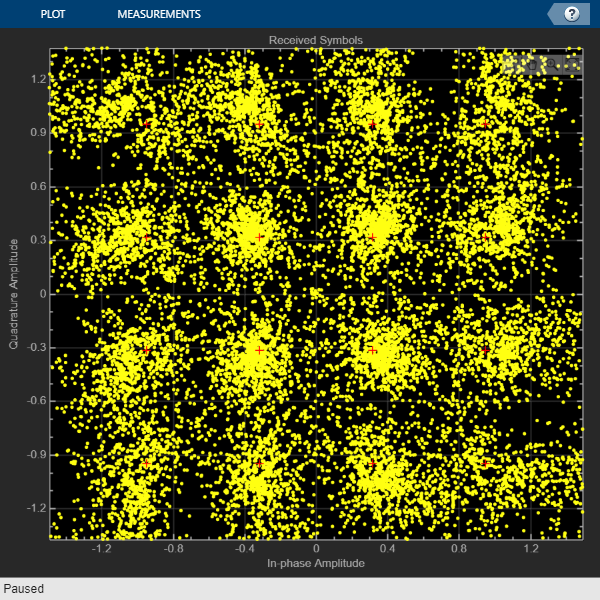

% Plot received constellation
scope(rxSym(:))

## Conclusion and Further Exploration

This example showed how you can use MATLAB's Python interface to test a pretrained CSINet model from Keras using a link simulation in MATLAB. The [5G Toolbox](https://www.mathworks.com/products/5g.html) in MATLAB is used to generate a data set of perfect channel estimates for a CDL channel model [3]. Python interpreter is called through MATLAB to test and fine-tune the weights of a pre-trained Keras network using the generated data set. MATLAB is then used to construct a precoder matrix from the output of the retrained network. Finally, an OFDM MIMO link is simulated in MATLAB to see the effect of CSINet compression on a zero-forcing precoder. 

Experiment with generating new data sets with different channel parameters and use it with different pretrained Keras networks to find the best initial weights for the selected channel model. You can also vary the compression rate of CSINet by setting the `compressRate` variable to a different value and see the effect of the compression rate on the received symbols constellation.

## References

[1] Wen, Chao-Kai, Wan-Ting Shih, and Shi Jin, "Deep learning for massive MIMO CSI feedback," IEEE Wireless Communications Letters, vol. 7, no. 5, pp. 748-751, Oct. 2018.

[2] https://github.com/sydney222/Python_CsiNet

[3] 3GPP TR 38.901. “Study on channel model for frequencies from 0.5 to 100 GHz.” *3rd Generation Partnership Project; Technical Specification Group Radio Access Network*.

### Local function

function nmse = computeNMSE(HTest, HhatCSINet)
% Calculate normalized MSE between test & predicted channel matrices

HTest = single(HTest);
HhatCSINet = single(HhatCSINet);
HTestComplex= complex(HTest(:,:,:,1),HTest(:,:,:,2));
power = sum(abs(HTestComplex).^2, 2:3);
nmse = 10.*log10(mean(sum(abs(HTest - HhatCSINet).^2, [2,3,4])./power));
end

function downnloadDataFile()
% Download data set and pretrained Keras network files to the current
% directory

dataFileName = {'processedData', 'keras'};
name  = {'data set', 'pretrained networks'};
dstFolder = pwd;
downloadAndExtractDataFile(dataFileName,dstFolder,name);
end

function downloadAndExtractDataFile(fileName,dstFolder,name)
for i = 1:2
    if exist(fileName{i},"dir")
        fprintf([fileName{i},' folder exists. Skip download.\n\n']);
    else
        fprintf(['Starting download ',name{i},'.\n'])
        fileFullPath = matlab.internal.examples.downloadSupportFile('spc/coexecutionPrecoding/',...
            [fileName{i},'.zip']);
        fprintf(['Downloading ',name{i},'. Extracting files.\n'])
        unzip(fileFullPath,dstFolder);
        fprintf('Extract complete.\n\n')
    end
end
end

*Copyright 2023 The MathWorks, Inc.*